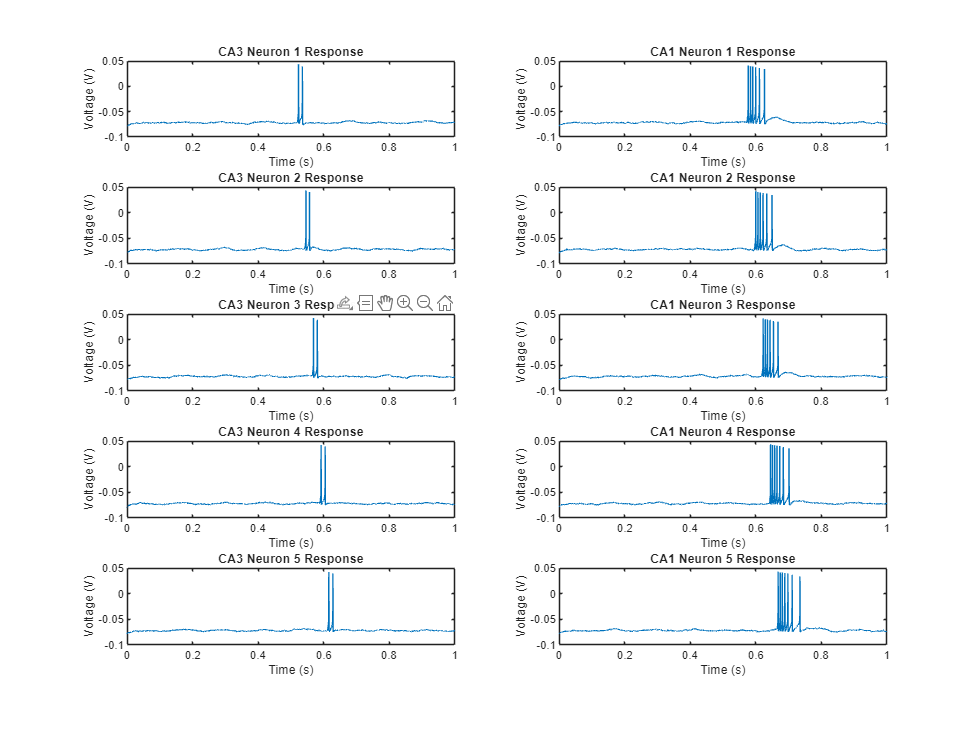


clf
clear

% Simulation parameters
t_range = [0 1];  % Time range for simulation

% Initialize input spikes for CA3_1 with a reasonable spike magnitude at t = 0.3s
inputSpikes_CA3_1 = [0.5 1e-7];  % Single excitatory spike with a more reasonable magnitude

% Simulate CA3 neurons
CA3_1 = ca3neuron(t_range, true, inputSpikes_CA3_1);
CA3_1Spikes = spikes_to_Iapp(CA3_1(:,1), CA3_1(:,2), false);

CA3_2 = ca3neuron(t_range, true, CA3_1Spikes);
CA3_2Spikes = spikes_to_Iapp(CA3_2(:,1), CA3_2(:,2), false);

CA3_3 = ca3neuron(t_range, true, CA3_2Spikes);
CA3_3Spikes = spikes_to_Iapp(CA3_3(:,1), CA3_3(:,2), false);

CA3_4 = ca3neuron(t_range, true, CA3_3Spikes);
CA3_4Spikes = spikes_to_Iapp(CA3_4(:,1), CA3_4(:,2), false);

CA3_5 = ca3neuron(t_range, true, CA3_4Spikes);
CA3_5Spikes = spikes_to_Iapp(CA3_5(:,1), CA3_5(:,2), false);

% Simulate CA1 neurons based on corresponding CA3 neuron spikes
CA1_1 = ca1neuron(t_range, true, CA3_1Spikes);
CA1_2 = ca1neuron(t_range, true, CA3_2Spikes);
CA1_3 = ca1neuron(t_range, true, CA3_3Spikes);
CA1_4 = ca1neuron(t_range, true, CA3_4Spikes);
CA1_5 = ca1neuron(t_range, true, CA3_5Spikes);


% Plot the responses of each CA3 neuron
figure;
subplot(5, 2, 1);
plot(CA3_1(:,1), CA3_1(:,2));
title('CA3 Neuron 1 Response');
xlabel('Time (s)');
ylabel('Voltage (V)');

subplot(5, 2, 3);
plot(CA3_2(:,1), CA3_2(:,2));
title('CA3 Neuron 2 Response');
xlabel('Time (s)');
ylabel('Voltage (V)');

subplot(5, 2, 5);
plot(CA3_3(:,1), CA3_3(:,2));
title('CA3 Neuron 3 Response');
xlabel('Time (s)');
ylabel('Voltage (V)');

subplot(5, 2, 7);
plot(CA3_4(:,1), CA3_4(:,2));
title('CA3 Neuron 4 Response');
xlabel('Time (s)');
ylabel('Voltage (V)');

subplot(5, 2, 9);
plot(CA3_5(:,1), CA3_5(:,2));
title('CA3 Neuron 5 Response');
xlabel('Time (s)');
ylabel('Voltage (V)');

% Plot the responses of each CA1 neuron
subplot(5, 2, 2);
plot(CA1_1(:,1), CA1_1(:,2));
title('CA1 Neuron 1 Response');
xlabel('Time (s)');
ylabel('Voltage (V)');

subplot(5, 2, 4);
plot(CA1_2(:,1), CA1_2(:,2));
title('CA1 Neuron 2 Response');
xlabel('Time (s)');
ylabel('Voltage (V)');

subplot(5, 2, 6);
plot(CA1_3(:,1), CA1_3(:,2));
title('CA1 Neuron 3 Response');
xlabel('Time (s)');
ylabel('Voltage (V)');

subplot(5, 2, 8);
plot(CA1_4(:,1), CA1_4(:,2));
title('CA1 Neuron 4 Response');
xlabel('Time (s)');
ylabel('Voltage (V)');

subplot(5, 2, 10);
plot(CA1_5(:,1), CA1_5(:,2));
title('CA1 Neuron 5 Response');
xlabel('Time (s)');
ylabel('Voltage (V)');

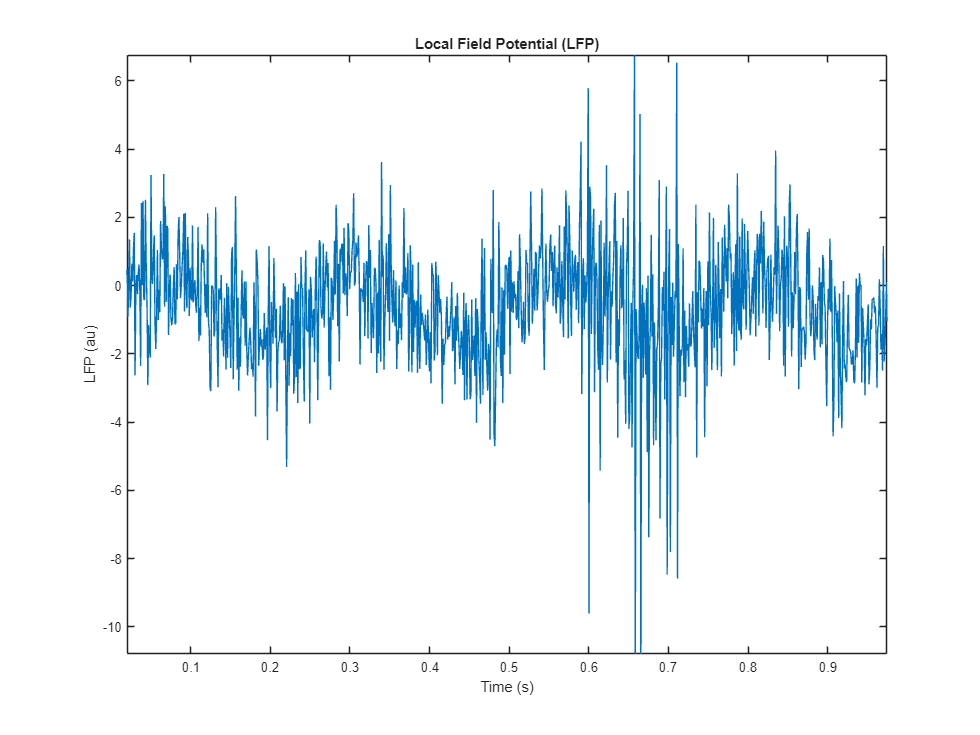


% Example usage of lfpMeasurementModel
% neuron_outputs should be a cell array where each cell contains [time, voltage] for each neuron


% Assuming CA1_1, CA1_2, CA1_3, CA1_4, CA1_5 are your CA1 neuron outputs
% Each of these variables should be a two-column matrix [time, voltage]
neuron_outputs = {CA1_1, CA1_2, CA1_3, CA1_4, CA1_5};

% Call the LFP measurement model
LFP = lfpMeasurementModel(t_range, 1000, neuron_outputs);

% Generate a sample signal
Fs = 1000;                   % Sampling frequency (Hz)
t = 0:1/Fs:1-1/Fs;           % Time vector (1 second)


% Compute FFT
n = length(LFP);          % Number of samples
f_transform = fft(LFP);   % Compute the FFT

% Compute the two-sided spectrum P2
P2 = abs(f_transform/n);

% Compute the single-sided spectrum P1
P1 = P2(1:n/2+1);

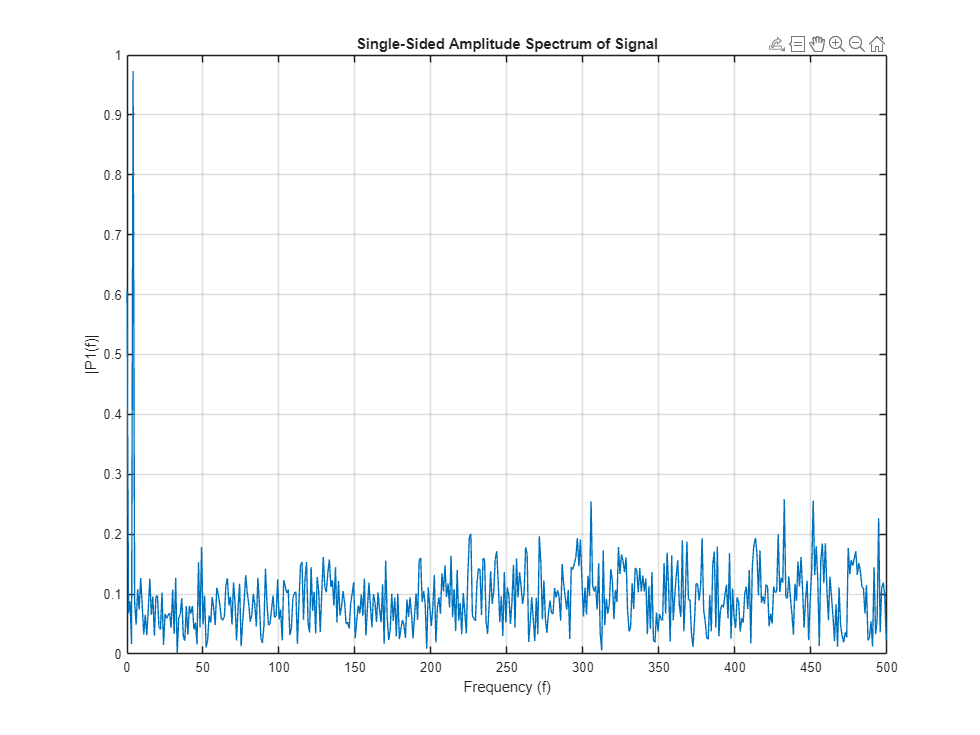

P1(2:end-1) = 2*P1(2:end-1);

% Define the frequency domain f
f = Fs*(0:(n/2))/n;

% Plot the single-sided amplitude spectrum
figure;
plot(f, P1)
title('Single-Sided Amplitude Spectrum of Signal')
xlabel('Frequency (f)')
ylabel('|P1(f)|')
grid on;

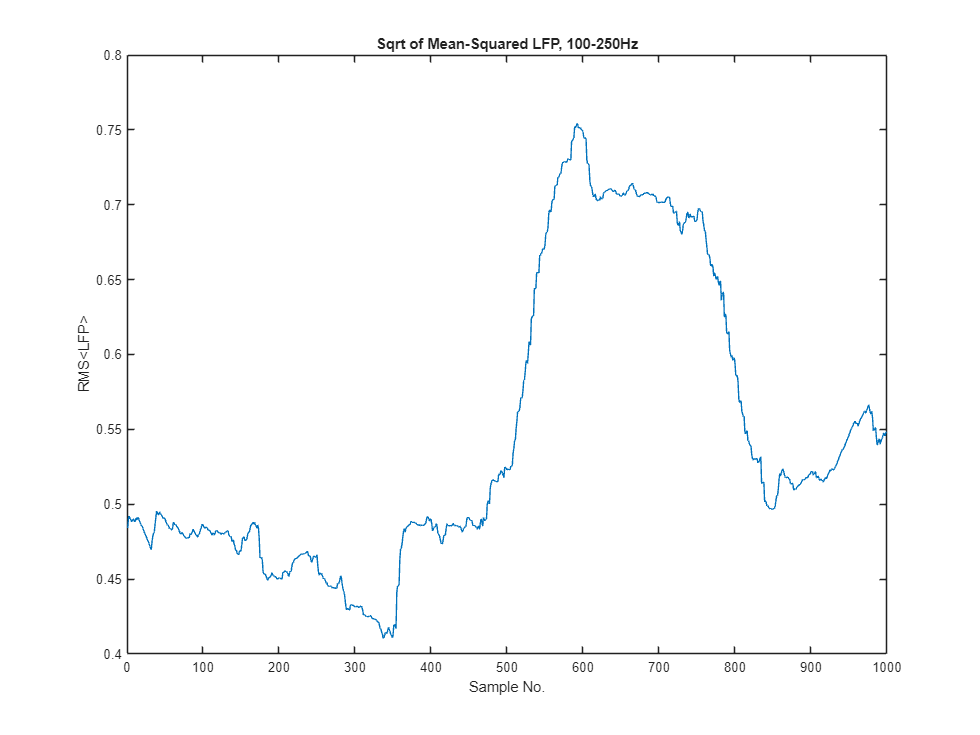

% Design a simple high-pass filter (cutoff at 100 Hz)
hp_cutoff = 100;
hp_filtered = LFP - movmean(LFP, round(1000 / hp_cutoff));

% Design a simple low-pass filter (cutoff at 250 Hz)
lp_cutoff = 250;
lp_filtered = movmean(hp_filtered, round(1000 / lp_cutoff));

csc_rms = sqrt(movmean(lp_filtered.^2, 250));
figure;
plot(csc_rms)
xlabel('Sample No.')
ylabel('RMS<LFP>')
title('Sqrt of Mean-Squared LFP, 100-250Hz')

function LFP = lfpMeasurementModel(t_range, n, neuron_outputs)
    % t_range: time range [t_start, t_end]
    % neuron_outputs: cell array where each cell contains a two-column matrix [time, voltage] for each neuron

    % Define the common time array for interpolation
    common_time = linspace(t_range(1), t_range(2), n);  % Example: 1000 points in the time range

    dt = t_range(2) - t_range(1) / n;

    % Preallocate an array to store interpolated voltages
    interpolated_voltages = zeros(length(common_time) - 1, length(neuron_outputs));
    
    % Random distances from the electrode for each CA1 neuron
    distances = rand(1, length(neuron_outputs)) * 0.1 + 0.1; % Random distances between 0.1 and 0.2 meters

    % Interpolate each neuron's output to the common time array
    for i = 1:length(neuron_outputs)
        time = neuron_outputs{i}(:, 1);
        voltage = neuron_outputs{i}(:, 2);
        interpolated_voltages(:, i) = diff(interp1(time, voltage, common_time, 'linear', 'extrap'))/dt;
    end

    % Compute the LFP using the inverse square law
    LFP = zeros(length(interpolated_voltages(:,1)),1);
    for i = 1:length(interpolated_voltages(1,:))
        LFP(:) = LFP(:) + interpolated_voltages(:, i) ./ (distances(i)^2);
    end
    
    new_time = linspace(t_range(1), t_range(2), length(LFP));

    noisyLFP = arrayfun(@(i) LFP(i) + sin(8*pi*new_time(i)) + 1.3*(randn-0.5), [1:length(new_time)]);

    LFP = noisyLFP;

    % Plot the LFP
    clf
    figure;
    plot(new_time, noisyLFP);
    title('Local Field Potential (LFP)');
    xlabel('Time (s)');
    ylabel('LFP (au)');
end

function spikeTimes = spikes_to_Iapp(tarray, varray, inhibitory)
    % Returns nx2 array, storing spikeTime and corresponding magnitude
    % Magnitude will be either +1 or -1 for excitatory or inhibitory input
    spikeTimes = [];
    if inhibitory
        for i = 2:length(varray)
            if varray(i-1) < 0 && varray(i) > 0
                spikeTimes(end+1,:) = [tarray(i) -1]; %#ok<*AGROW>
            end
        end
    else
        for i = 2:length(varray)
            if varray(i-1) < 0 && varray(i) > 0
                spikeTimes(end+1,:) = [tarray(i) 1]; %#ok<*AGROW>
            end
        end
    end
end

function out = ca3neuron(t_range, inhibitory, inputSpikes)
    pars.gleak = 10e-9;
    pars.gnamax = 3.6e-6;
    pars.gkmax = 1.6e-6;
    pars.gtmax = 0.22e-6;
    pars.ena = 55e-3;
    pars.ek = -90e-3;
    pars.eca = 120e-3;
    pars.el = -70e-3;
    pars.cm = 100e-12;
    pars.baselinecurrent = 0;
    pars.baseCurrentFrq = 0;
    pars.inputSpikes = inputSpikes;
    pars.tau = 0.005;
    pars.sumWeight = 0.7;
    pars.spikeDelay = 0.02;

    if inhibitory
        pars.baseCurrentFrq = 8;
    end

    t0 = t_range(1);
    tf = t_range(2);

    % Ensure inputSpikes is correctly initialized
    if isempty(pars.inputSpikes)
        pars.inputSpikes = zeros(0,2); % Initialize as an empty nx2 array
    end

    % Read inputs here
    pars.currentsteps = [];
    
    %options = odeset('RelTol',1e-6,'AbsTol',1e-8, 'MaxStep', 1e-4);
    [tout,xout] = ode45(@(t,x) thalamic_rebound(t,x,pars), [t0 tf],[-78e-3; 0;0;0]);

    out = [tout, xout(:,1)];
end

function out = ca1neuron(t_range, inhibitory, inputSpikes)
    pars.gleak = 10e-9;
    pars.gnamax = 3.6e-6;
    pars.gkmax = 1.6e-6;
    pars.gtmax = 0.22e-6;
    pars.ena = 55e-3;
    pars.ek = -90e-3;
    pars.eca = 120e-3;
    pars.el = -70e-3;
    pars.cm = 100e-12;
    pars.baselinecurrent = 0;
    pars.baseCurrentFrq = 0;
    pars.inputSpikes = inputSpikes;
    pars.tau = 0.03;
    pars.sumWeight = 0.5;
    pars.spikeDelay = 0.05;

    if inhibitory
        pars.baseCurrentFrq = 8;
    end

    t0 = t_range(1);
    tf = t_range(2);

    % Ensure inputSpikes is correctly initialized
    if isempty(pars.inputSpikes)
        pars.inputSpikes = zeros(0,2); % Initialize as an empty nx2 array
    end

    % Read inputs here
    pars.currentsteps = [];
    
    %options = odeset('RelTol',1e-6,'AbsTol',1e-8, 'MaxStep', 1e-4);
    [tout,xout] = ode45(@(t,x) thalamic_rebound(t,x,pars), [t0 tf],[-78e-3; 0;0;0]);

    out = [tout, xout(:,1)];
end

function dxdt = thalamic_rebound(t,x, pars)
    V = x(1);
    h = x(2);
    n = x(3);
    ht = x(4);

    GL = pars.gleak;
    GNa = pars.gnamax;
    GK = pars.gkmax;
    GT = pars.gtmax; 
    ENa = pars.ena;
    EK = pars.ek;
    ECa = pars.eca;
    EL = pars.el;
    Cm = pars.cm;
    BL = pars.baselinecurrent;
    frq = pars.baseCurrentFrq;
    inputSpikes = pars.inputSpikes(:,1);
    inputMagnitude = pars.inputSpikes(:,2);
    tau = pars.tau;
    sumWeight = pars.sumWeight;
    spikeDelay = pars.spikeDelay;

    inputCurrent = 0;
    spikeCurrents = [];
    if ~isempty(inputSpikes)
        spikeIndices = find(inputSpikes < (t - spikeDelay) & inputSpikes > (t - 5*spikeDelay));  % Find all spikes before current time
        for idx = spikeIndices'
            spikeTimeDiff = inputSpikes(idx) - (t - spikeDelay);  % This value will be negative
            spikeCurrents(end+1) = exp(spikeTimeDiff / tau) * 1e-9;  % Sum the contributions
        end
    end
    if ~isempty(spikeCurrents)
        inputCurrent = sum(spikeCurrents)*sumWeight/length(spikeCurrents);
    end
    %if ~isempty(inputSpikes)
    %    lastSpikeTimeIndex = find(inputSpikes < t, 1, 'last');        
    %    if ~isempty(lastSpikeTimeIndex)
    %        lastSpikeTime = inputSpikes(lastSpikeTimeIndex);
    %        spikeTimeDiff = lastSpikeTime - t; % this value will be negative
    %        inputCurrent = exp(spikeTimeDiff/0.01) * inputMagnitude(lastSpikeTimeIndex) * 1e-9; % 50ms exponential decay
    %    end
    %end
    
    

    Iosc = 0;
    if frq ~= 0
        Iosc = (sin(2*pi*t*frq)-1)*1e-11;
    end

    Iapp = inputCurrent + Iosc + (randn-0.5)*5e-11;

    if V == -35e-3
        am = 1e3;
    else
        am  = (1e5)*(V + 0.035)/(eps + 1 - exp(-100*(V+0.035)));
    end
    bm = 4000*exp(-1*(V+0.06)/(0.018));
    m = am / (am + bm + eps);
    
    ah = 350*exp(-50*(V+0.058));
    bh = 5000/(1 + exp(-100*(V+0.028)));
    dhdt = ah*(1-h) - bh*h;

    if V == -34e-3
        an = 500;
    else
        an = (5e4)*(V+0.034)/(eps + 1 - exp(-100*(V+0.034)));
    end
    bn = 625*exp(-12.5*(V+0.044));
    dndt = an*(1-n) - bn*n;

    mt = 1/(1 + exp(-1*(V+0.052)/0.0074));

    htss = 1/(1 + exp(500*(V+0.076)));
    if V < -0.080
        tht = 0.001*exp(15*(V+0.467));
    else
        tht = 0.028 + 0.001*exp(-(V+0.022)/0.0105);
    end
    dhtdt = (htss - ht) / (tht + eps);

    dVdt = (1/Cm)*(GL*(EL - V) + GNa*(h*m^3)*(ENa - V) + GK*(n^4)*(EK - V) + GT*(ht*mt^2)*(ECa - V) + eps + Iapp);
 
    dxdt = [ dVdt; dhdt; dndt; dhtdt];
end
